# Laboratoire 1

## Exercise 1

clc
close all
clear all

## a)

TD = [0.0 0.2 0.5 1.0 2.5 5.0];
K_p = 1;
W_n = 1;
Zeta = 0.1;
Couleur = ['r' 'g' 'b' 'm' 'y' 'c' 'k'];
Fig1 = figure;
Fig2 = figure;

num1 = [W_n^2];
den1 = [1 2*Zeta*W_n W_n^2];
FT1 = tf(num1,den1);

% Faire le gain des racines
for i = 1:length(TD)
    num2 = [K_p*TD(i) K_p];
    den2 = [1];
    
    FT2 = tf(num2,den2);

    FT = FT1*FT2;
    FT_Fermer = FT/(1+FT);

    p = rlocus(FT, K_p);
    
    figure(Fig1)
    rlocus(FT, Couleur(i))
    hold on
    plot(real(p), imag(p), 'x', 'MarkerSize',5) 
    hold on

    figure(Fig2)
    step(FT_Fermer, Couleur(i))
    hold on
end

## B)

close all
%Faire les step responses
Fig3 = figure;
Fig4 = figure;
Tau = [0.0 0.01 0.05 0.1 0.2]; 

for ii = 1:length(Tau)
    num2 = [1];
    den2 = [Tau(ii) 1];

    FT2 = tf(num2,den2);

    FT = series(FT1,FT2); % Cela fait un *

    FT_Fermer = feedback(FT, 1); % cela fait FT/(1 + k*FT)
    p = rlocus(FT, K_p);
    
    figure(Fig3)
    rlocus(FT, Couleur(ii))
    hold on
    plot(real(p), imag(p), 'x', 'MarkerSize',5) 
    hold on

    figure(Fig4)
    step(FT_Fermer, Couleur(ii))
    hold on
end


## Exercise 2

close all
clear all
clc

Fig5 = figure;
Fig6 = figure;

K_p = 1
TR = [0.05 0.10 0.20 0.25]
W_n = 1;
Zeta = 0.1;
Couleur = ['r' 'g' 'b' 'm' 'y' 'c' 'k'];

num1 = [W_n^2];
den1 = [1 2*Zeta*W_n W_n^2];
FT1 = tf(num1,den1);

for iii = 1:length(TR)
    Cap = tf([-TR(iii) 0], [0 1]);
    FT2 = pade(exp(Cap), 5);

    FT = series(FT1,FT2); % Cela fait un *

    FT_Fermer = feedback(FT, 1); % cela fait FT/(1 + k*FT)
    p = rlocus(FT, K_p);FT = series(FT1,FT2); % Cela fait un *

    FT_Fermer = feedback(FT, 1); % cela fait FT/(1 + k*FT)
    p = rlocus(FT, K_p);

    figure(Fig5)
    step(FT_Fermer, Couleur(iii))
    xlim([0 50])
    hold on

    figure(Fig6)
    rlocus(FT, Couleur(iii))
    hold on
    plot(real(p), imag(p), 'x', 'MarkerSize',5) 
    hold on
end


## Exercise 3

Fig7 = figure;
Fig8 = figure;

H = tf([4], [1 2 0]);
G1 = 1;
G2 = tf([4.68 4.68*2.9], [4.68 4.68*5.4]);
G3 = tf([4.68 2.9*4.68], [4.68*5.4]);

% a)
FT = series(G1, H);
FT_Fermer = feedback(FT, 1);

figure(Fig7)
step(FT_Fermer, Couleur(1))
stepinfo(FT_Fermer)

ans = struct with fields:
         RiseTime: 0.8195
    TransientTime: 4.0379
     SettlingTime: 4.0379
      SettlingMin: 0.9315
      SettlingMax: 1.1629
        Overshoot: 16.2929
       Undershoot: 0
             Peak: 1.1629
         PeakTime: 1.7960


hold on
figure(Fig8)
rlocus(FT, Couleur(1))
hold on

% b)
FT = series(G2, H);
FT_Fermer = feedback(FT, 1);

figure(Fig7)
step(FT_Fermer, Couleur(2))
stepinfo(FT_Fermer)

ans = struct with fields:
         RiseTime: 1.5252
    TransientTime: 2.3301
     SettlingTime: 2.3301
      SettlingMin: 0.9001
      SettlingMax: 1.0118
        Overshoot: 1.1771
       Undershoot: 0
             Peak: 1.0118
         PeakTime: 3.3399


hold on
figure(Fig8)
rlocus(FT, Couleur(2))
hold on

% c)
FT = series(G3, H);
FT_Fermer = feedback(FT, 1);

figure(Fig7)
step(FT_Fermer, Couleur(3))
stepinfo(FT_Fermer)

ans = struct with fields:
         RiseTime: 1.8661
    TransientTime: 3.0011
     SettlingTime: 3.0011
      SettlingMin: 0.9023
      SettlingMax: 1.0003
        Overshoot: 0.0333
       Undershoot: 0
             Peak: 1.0003
         PeakTime: 5.3432


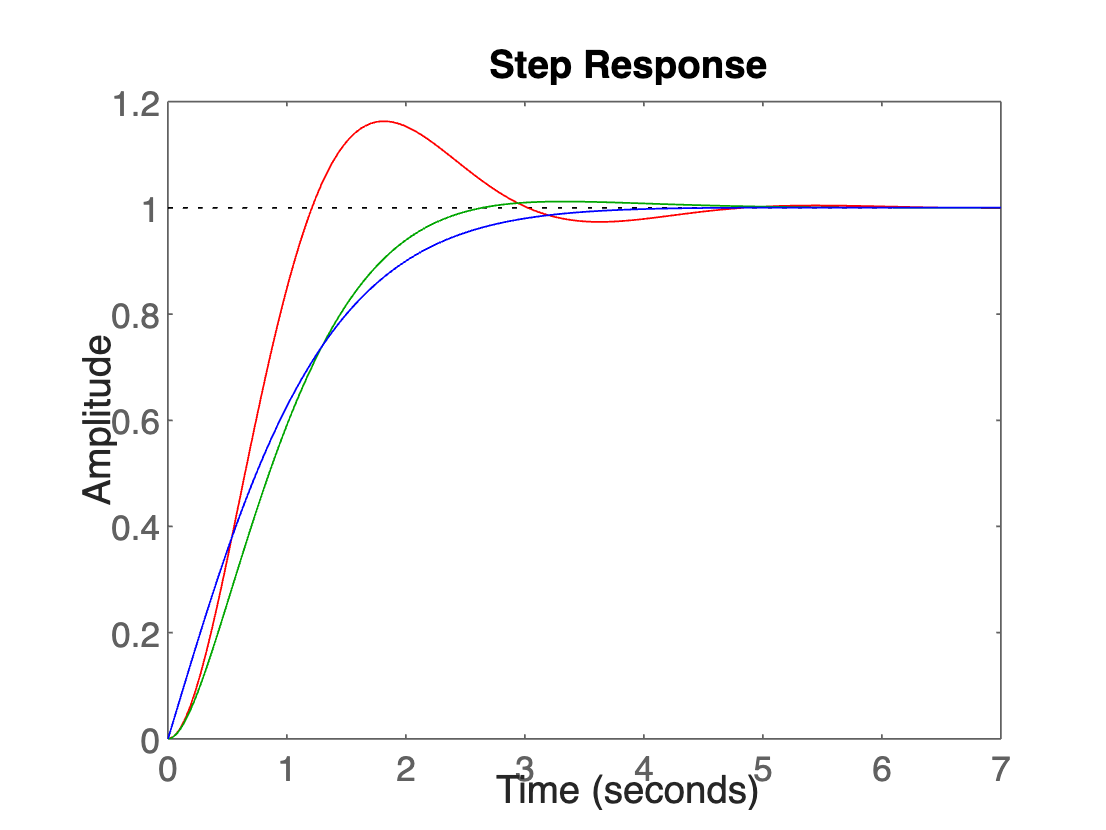

hold on

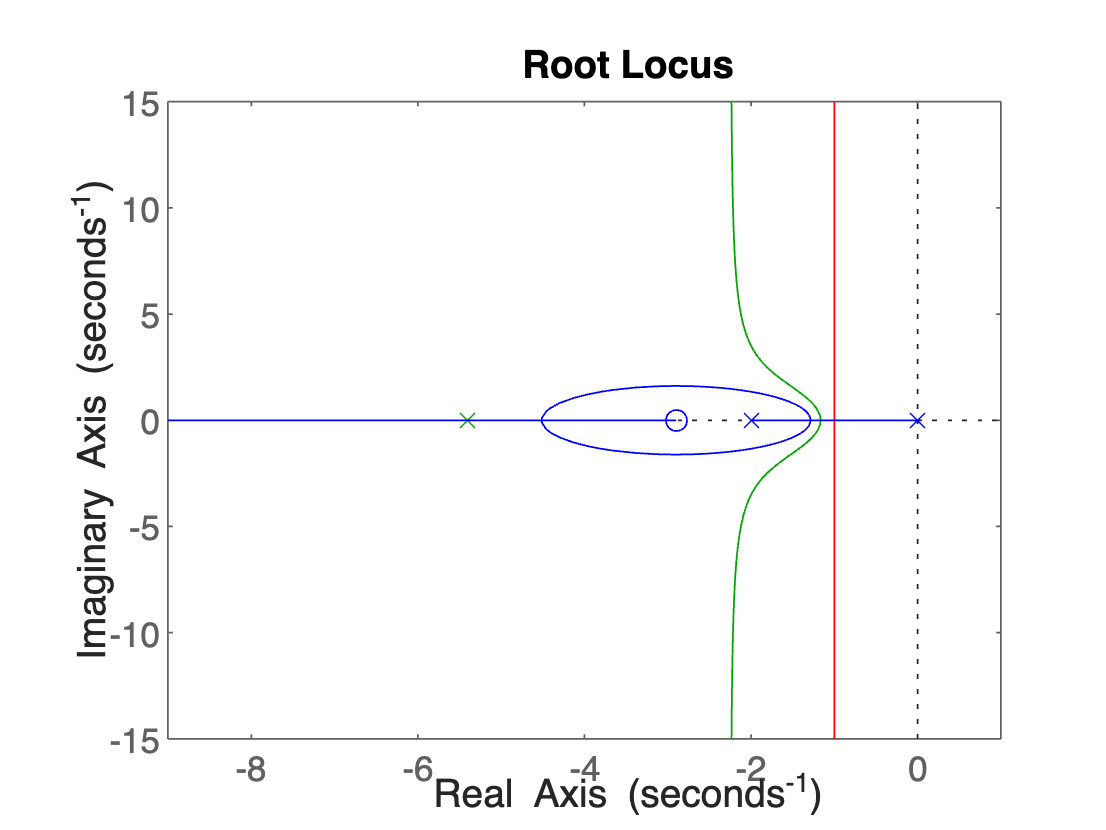

figure(Fig8)
rlocus(FT, Couleur(3))
hold on